# Analyze EPL Results

Merge team information (such as manager and payroll) with results, to look for factors that might affect team performance.

## Import and Combine Data From Two Sources

results = readtable("EPLFinalStandings.csv",TextType="string")

results = 20×8 table
             Team             TotalWins    TotalDraws    TotalLosses    TotalGF    TotalGA    GoalDiff    Points
    ______________________    _________    __________    ___________    _______    _______    ________    ______
    "Leicester City"             23            12             3           68         36          32         81  
    "Arsenal"                    20            11             7           65         36          29         71  
    "Tottenham Hotspur"          19            13             6           69         35          34         70  
    "Manchester City"            19             9            10           71         41          30         66  
    "Manchester United"      

teamInfo = readtable("EPLteams.csv",TextType="string")

teamInfo = 20×5 table
           Team            Payroll_M__          Manager           ManagerHireDate    ManagerNationality
    ___________________    ___________    ____________________    _______________    __________________
    "Arsenal"                   192       "Arsène Wenger"          "01 Oct 1996"       "France"        
    "Aston Villa"              65.1       "Eric Black"             "29 Mar 2016"       "Scotland"      
    "Bournemouth"                25       "Eddie Howe"             "12 Oct 2012"       "England"       
    "Chelsea"                 215.6       "Guus Hiddink"           "19 Dec 2015"       "Netherlands"   
    "Crystal Palace"           54.3       "Alan Pardew"            "02 Jan 2015"       "England"       
    "Everton"                  74.7       "David Unsworth"         "12 May 2016"

Join tables, using the team names as the key variable

results = join(results,teamInfo)

results = 20×12 table
             Team             TotalWins    TotalDraws    TotalLosses    TotalGF    TotalGA    GoalDiff    Points    Payroll_M__            Manager            ManagerHireDate    ManagerNationality
    ______________________    _________    __________    ___________    _______    _______    ________    ______    ___________    _______________________    _______________    __________________
    "Leicester City"             23            12             3           68         36          32         81          48.2       "Claudio Ranieri"           "13 Jul 2015"      

## Clean Up Table Properties

The header for the payroll variable contains characters that are not valid in a variable name. These characters are automatically converted to "_". 

disp(results.Properties.VariableNames)

    {'Team'}    {'TotalWins'}    {'TotalDraws'}    {'TotalLosses'}    {'TotalGF'}    {'TotalGA'}    {'GoalDiff'}    {'Points'}    {'Payroll_M__'}    {'Manager'}    {'ManagerHireDate'}    {'ManagerNationality'}


Rename the payroll variable to something more readable.

results = renamevars(results,"Payroll_M__","Payroll")

results = 20×12 table
             Team             TotalWins    TotalDraws    TotalLosses    TotalGF    TotalGA    GoalDiff    Points    Payroll            Manager            ManagerHireDate    ManagerNationality
    ______________________    _________    __________    ___________    _______    _______    ________    ______    _______    _______________________    _______________    __________________
    "Leicester City"             23            12             3           68         36          32         81        48.2     "Claudio Ranieri"           "13 Jul 2015"       "Italy"    

Convert the manager nationality from string to categorical.

results = convertvars(results,"ManagerNationality","categorical")

results = 20×12 table
             Team             TotalWins    TotalDraws    TotalLosses    TotalGF    TotalGA    GoalDiff    Points    Payroll            Manager            ManagerHireDate    ManagerNationality
    ______________________    _________    __________    ___________    _______    _______    ________    ______    _______    _______________________    _______________    __________________
    "Leicester City"             23            12             3           68         36          32         81        48.2     "Claudio Ranieri"           "13 Jul 2015"        Italy     

The manager hire dates are in a format that is not automatically recognized. Hence, this variable is imported as a string, rather than as a datetime.

disp(class(results.ManagerHireDate))

string


In this case, trying to use convertvars to convert to datetime will not work, because the date format is not recognized

Instead, use the `datetime` function to convert manually.

results.ManagerHireDate = datetime(results.ManagerHireDate,InputFormat="dd MMM uuuu",Locale="en_GB")

results = 20×12 table
             Team             TotalWins    TotalDraws    TotalLosses    TotalGF    TotalGA    GoalDiff    Points    Payroll            Manager            ManagerHireDate    ManagerNationality
    ______________________    _________    __________    ___________    _______    _______    ________    ______    _______    _______________________    _______________    __________________
    "Leicester City"             23            12             3           68         36          32         81        48.2     "Claudio Ranieri"            13-Jul-2015         Italy     

## Look For Factors Influencing Results

Manager nationality

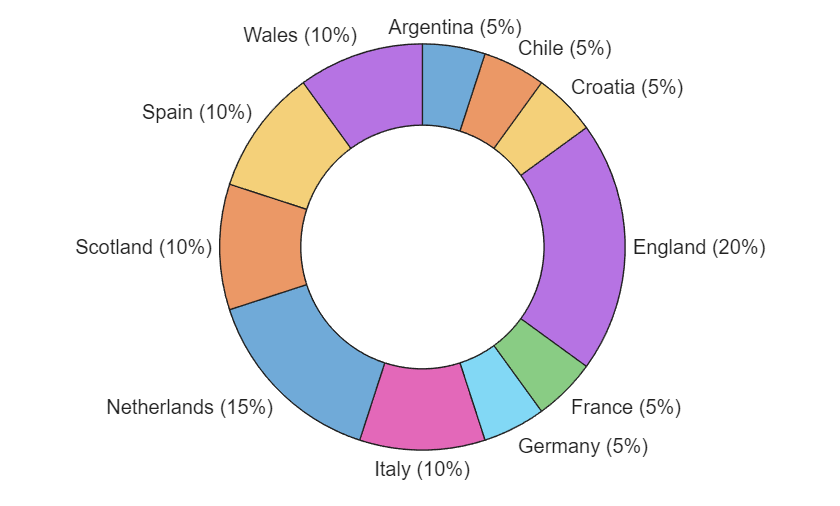

donutchart(results.ManagerNationality)

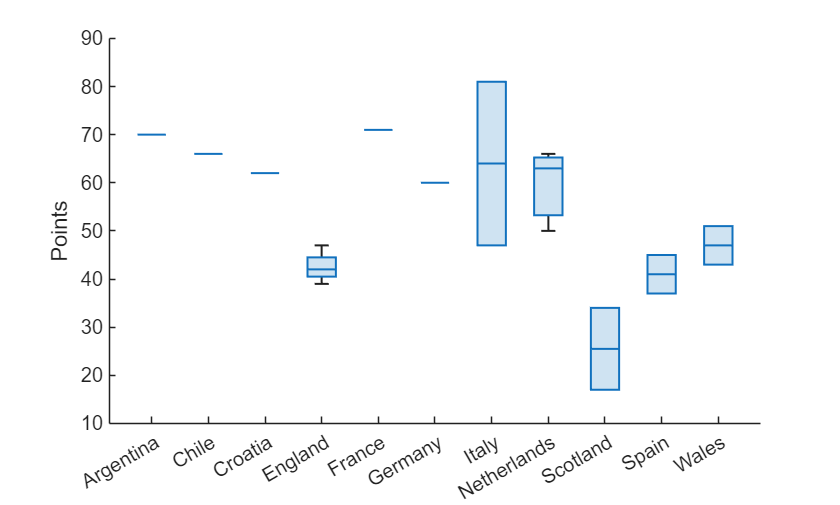

boxchart(results.ManagerNationality,results.Points)
ylabel("Points")

Manager tenure

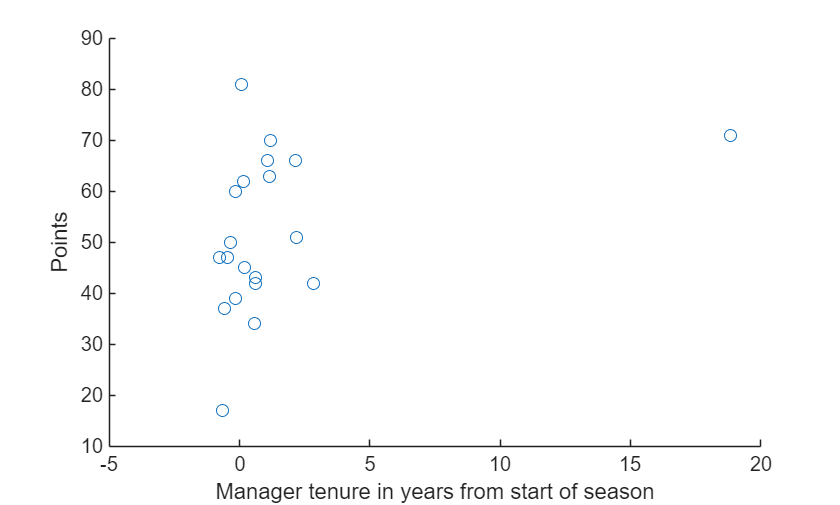

seasonstart = datetime(2015,8,8);
tenure = years(seasonstart - results.ManagerHireDate);
scatter(tenure,results.Points)
xlabel("Manager tenure in years from start of season")
ylabel("Points")

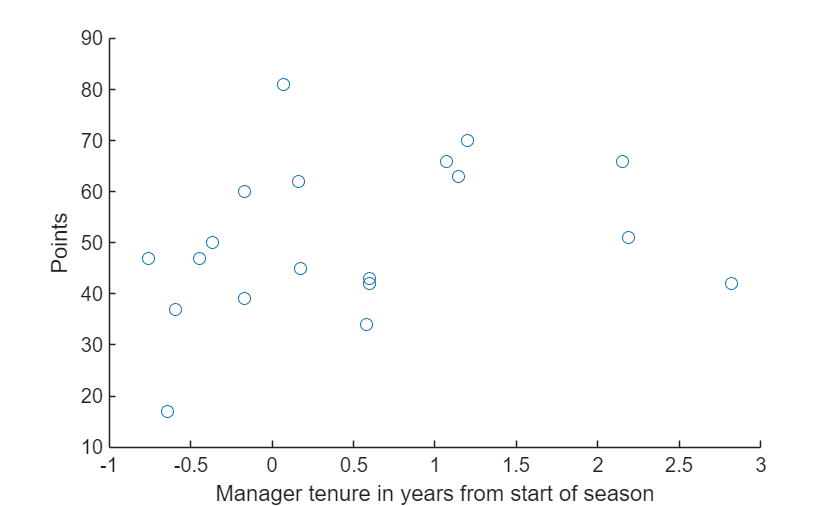


% Zoom in to exclude Arsène Wenger
scatter(tenure,results.Points)
xlim([-1 3])
xlabel("Manager tenure in years from start of season")
ylabel("Points")

Payroll

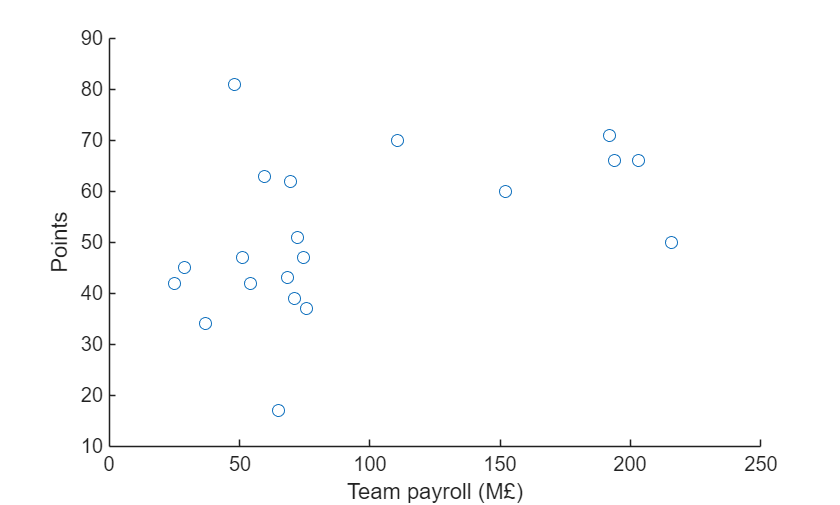

scatter(results.Payroll,results.Points)
xlabel("Team payroll (M£)")
ylabel("Points")